TASK E

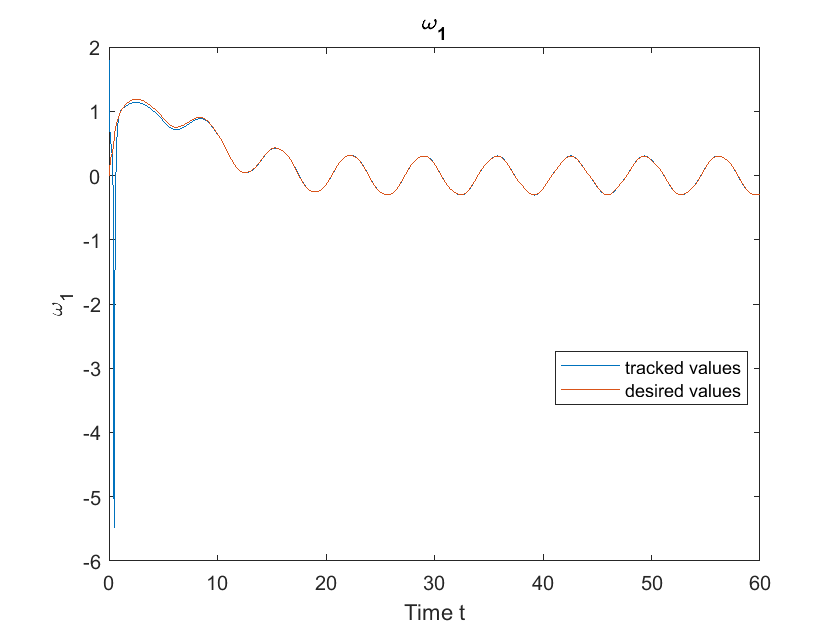

%Solve for S
J = [20 1.2 0.9; 1.2 17 1.4; 0.9 1.4 15];
Jinv = inv(J);
J0 = [14 0.84 0.63 11.9 0.98 10.5];
qv0 = [0.1826 0.1826 0.1826];
q0 = sqrt(1 - norm(qv0)^2);
q = [q0 qv0];
R_q = q_to_R(q);
qd = [1 0 0 0];
R_qd = q_to_R(qd);
Rs = mtimes(R_q,R_qd');
%solve for error dynamics
sv0 = [0.1826 0.1826 0.1826];
s0 = sqrt(1 - norm(sv0)^2);
%initialize w at t=0, then calculate it form del w = w -Rswd
w = [1.8; 1.2; 1.4];
wdt0 = [0; 0; 1];
dw0 = (w - mtimes(Rs,wdt0))';
y0 = [s0 sv0 dw0 J0];

tspan = [0 60];
kpsi = 20;
kp = 30;
g = 1;
opts = odeset('RelTol',1e-6,'AbsTol',1e-8);
[t,y] = ode45(@(t,y) adaptiveJ(t,y,kpsi,J,Jinv,kp,g), tspan, y0,opts);

[l,n] = size(y);
omega1 = zeros(l,1);
omega2 = zeros(l,1);
omega3 = zeros(l,1);
omegad1 = zeros(l,1);
omegad2 = zeros(l,1);
omegad3 = zeros(l,1);
omegad1dot = zeros(l,1);
omegad2dot = zeros(l,1);
omegad3dot = zeros(l,1);
e11 = zeros(l,1);
e12 = zeros(l,1);
e13 = zeros(l,1);
e22 = zeros(l,1);
e23 = zeros(l,1);
e33 = zeros(l,1);
u1 = zeros(l,1);
u2 = zeros(l,1);
u3 = zeros(l,1);
for i = 1:l
    e11(i) = y(i,8)-20;
    e12(i) = y(i,9)-1.2;
    e13(i) = y(i,10)-0.9;
    e22(i) = y(i,11)-17;
    e23(i) = y(i,12)-1.4;
    e33(i) = y(i,13)-15;
    Rswd = Rs_wd(y(i,1:4),i,l);
    wd = wdes(i,l);
    wddot = wdesdot(i,l);
    omega1(i) = y(i,5) + Rswd(1);
    omega2(i) = y(i,6) + Rswd(2);
    omega3(i) = y(i,7) + Rswd(3);
    omegad1(i) = wd(1);
    omegad2(i) = wd(2);
    omegad3(i) = wd(3); 
    omegad1dot(i) = wddot(1);
    omegad2dot(i) = wddot(2);
    omegad3dot(i) = wddot(3); 
end

for i = 1:l
    Rs = q_to_R(y(i,1:4));
    wd = [omegad1(i);omegad2(i);omegad3(i)];
    wddot = [omegad1dot(i);omegad2dot(i);omegad3dot(i)];
    wc = [omega1(i);omega2(i);omega3(i)];
    Jh = mx_conv(y(i,8:13));
    wJhw = cross(wc,mtimes(Jh,wc));
    phi = mtimes(mtimes(-y(i,5:7),Rs),wd) + mtimes(Rs,wddot);
    psi = y(i,5:7) + kp*y(i,2:4);
    Jhphi = mtimes(Jh,phi);
    Jhsv = y(i,1)*mtimes(Jh,y(i,5:7)') + mtimes(Jh,cross(y(i,2:4),y(i,5:7))');
    u1(i) = -kp*Jhsv(1)-kpsi*psi(1)+ wJhw(1)+Jhphi(1);
    u2(i) = -kp*Jhsv(2)-kpsi*psi(2)+ wJhw(2)+Jhphi(2);
    u3(i) = -kp*Jhsv(2)-kpsi*psi(3)+ wJhw(3)+Jhphi(3);
end
plot(t,omega1)
hold on
plot(t,omegad1)
title('\omega_1');
xlabel('Time t');
ylabel('\omega_1');
legend('tracked values','desired values',"Location","best")

hold off

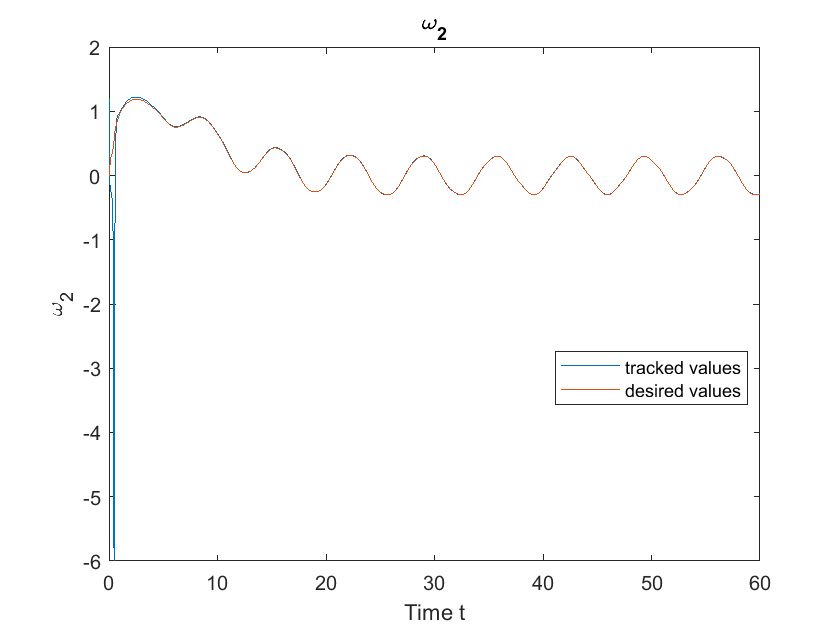

plot(t,omega2)
hold on
plot(t,omegad2)
title('\omega_2');
xlabel('Time t');
ylabel('\omega_2');
legend('tracked values','desired values',"Location","best")

hold off

plot(t,omega3)
hold on
plot(t,omegad3)
title('\omega_3');
xlabel('Time t');
ylabel('\omega_3');
legend('tracked values','desired values',"Location","best")

PLOTS 

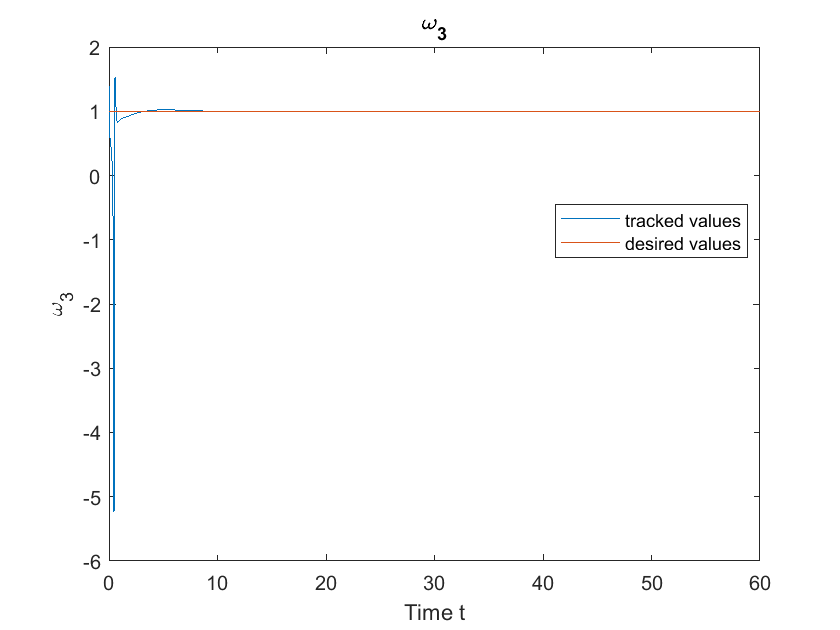


hold off

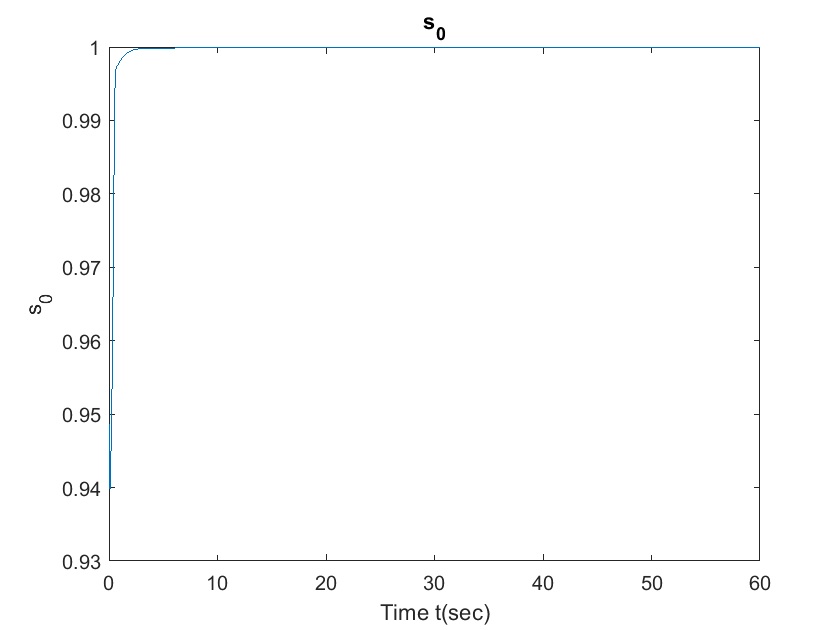

plot(t,y(:,1))
title('s_0');
xlabel('Time t(sec)');
ylabel('s_0');


hold off

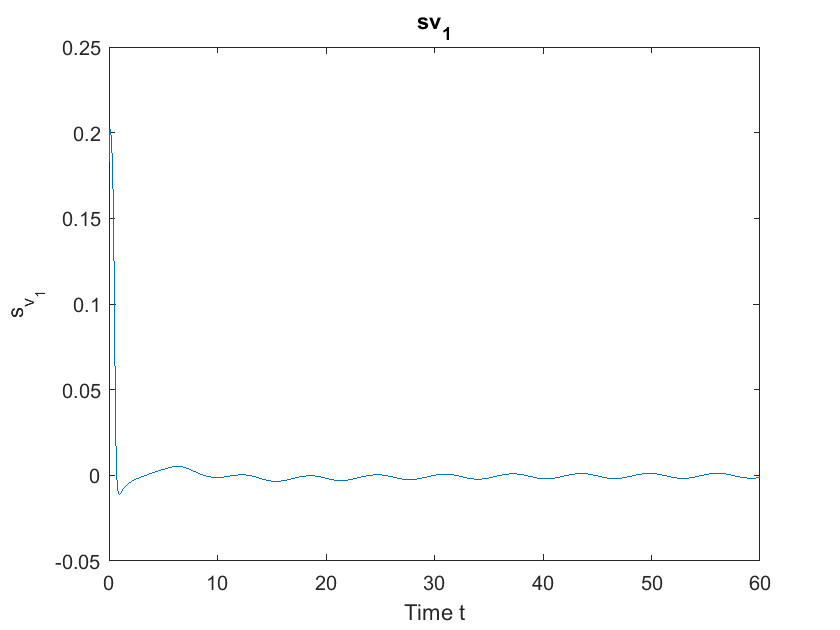

plot(t,y(:,2))
title('sv_1');
xlabel('Time t');
ylabel('s_{v_1}');

hold off

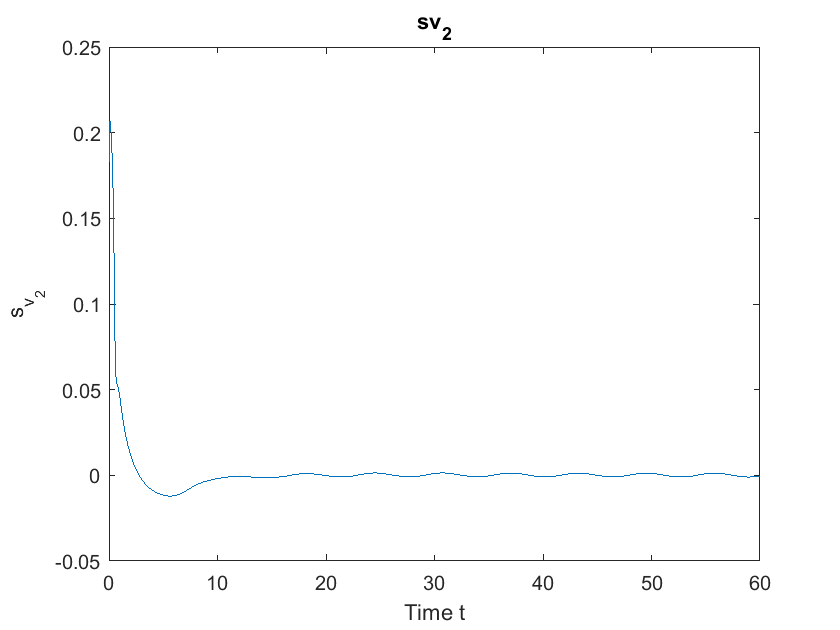

plot(t,y(:,3))
title('sv_2');
xlabel('Time t');
ylabel('s_{v_2}');

hold off

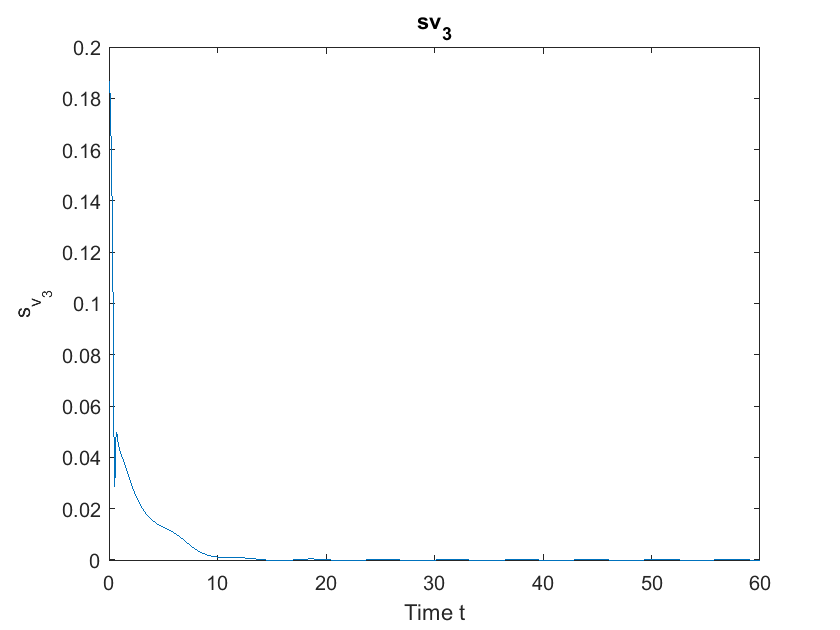

plot(t,y(:,4))
title('sv_3');
xlabel('Time t');
ylabel('s_{v_3}');

hold off

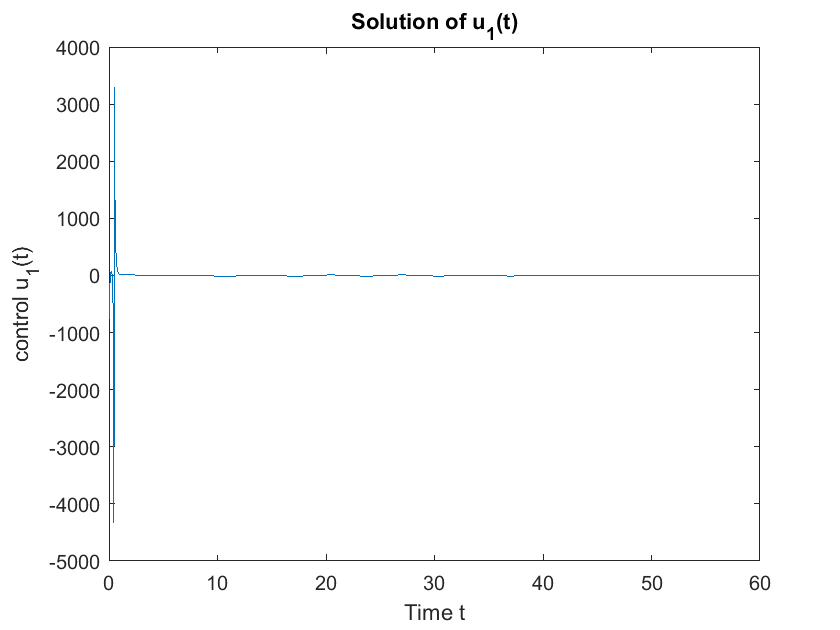

plot(t,u1)
title('Solution of u_1(t)');
xlabel('Time t');
ylabel('control u_1(t)');

hold off

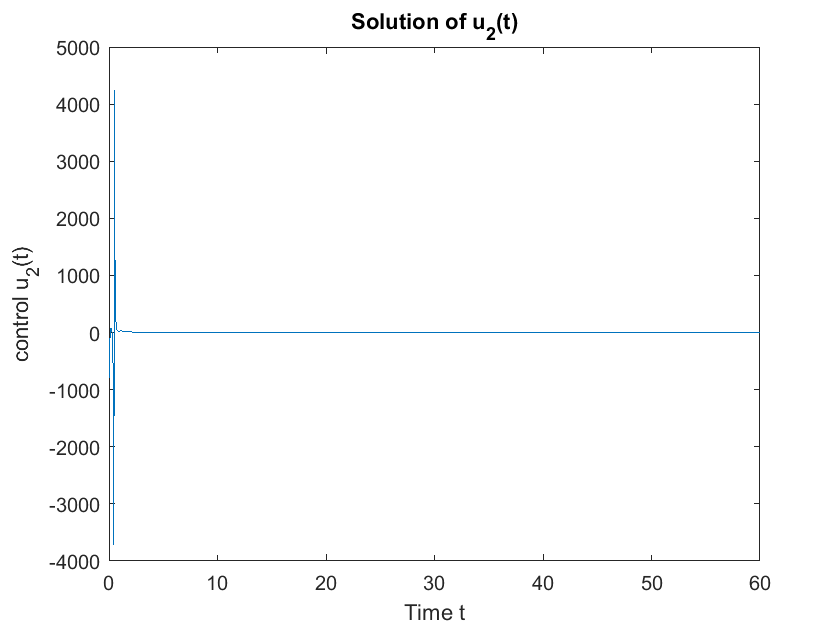

plot(t,u2)
title('Solution of u_2(t)');
xlabel('Time t');
ylabel('control u_2(t)');

hold off

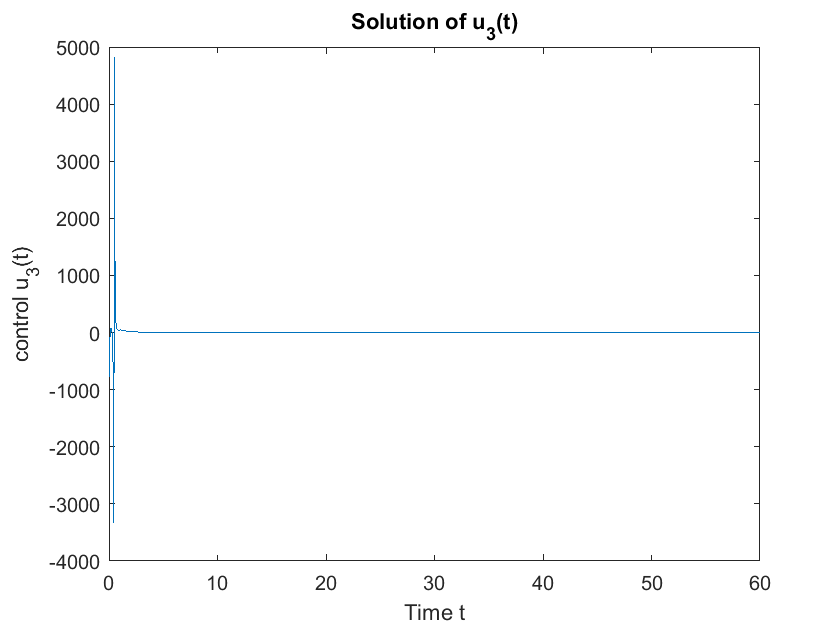

plot(t,u3)
title('Solution of u_3(t)');
xlabel('Time t');
ylabel('control u_3(t)');

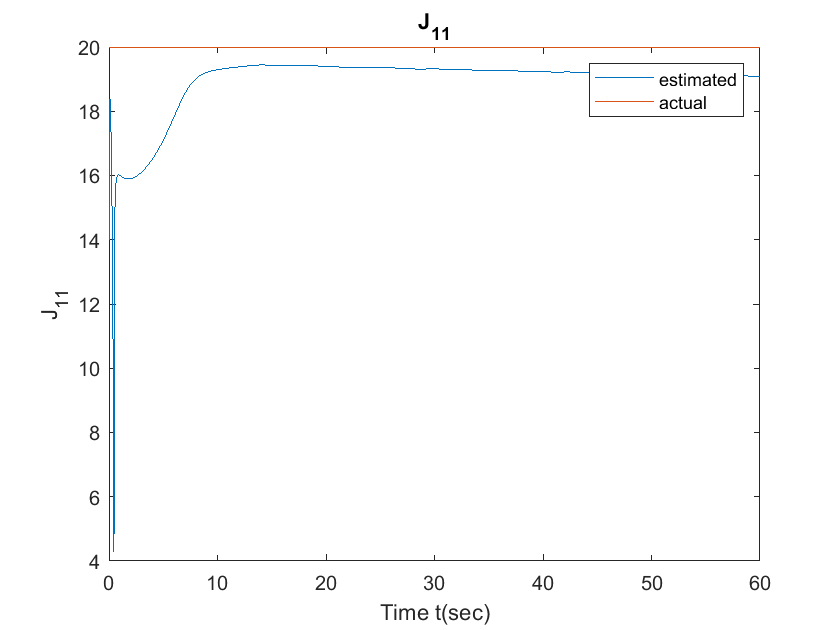


plot(t,y(:,8))
hold on
plot([0 10 20 30 40 50 60],[20 20 20 20 20 20 20])
title('J_{11}');
xlabel('Time t(sec)');
ylabel('J_{11}');
legend('estimated','actual')

hold off

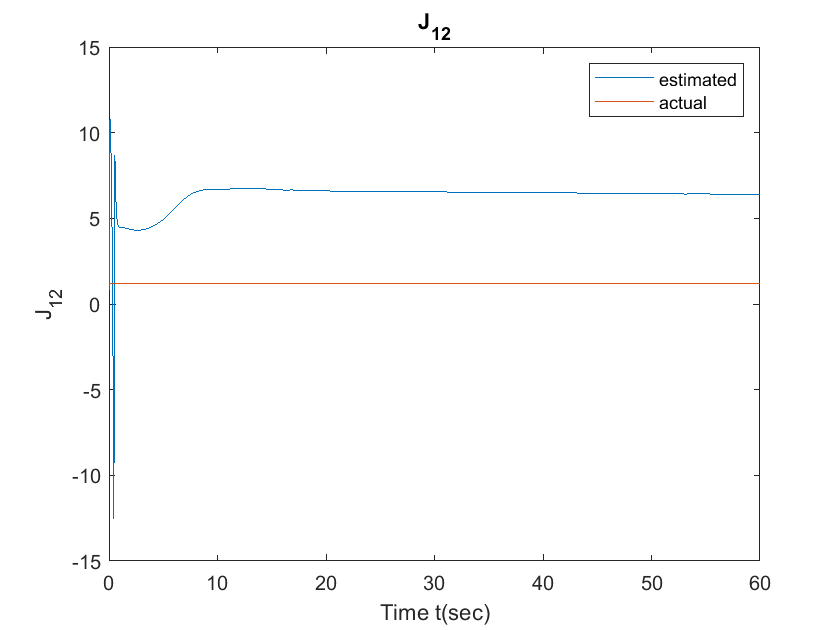

plot(t,y(:,9))
hold on
plot([0 10 20 30 40 50 60],[1.2 1.2 1.2 1.2 1.2 1.2 1.2])
title('J_{12}');
xlabel('Time t(sec)');
ylabel('J_{12}');
legend('estimated','actual')

hold off

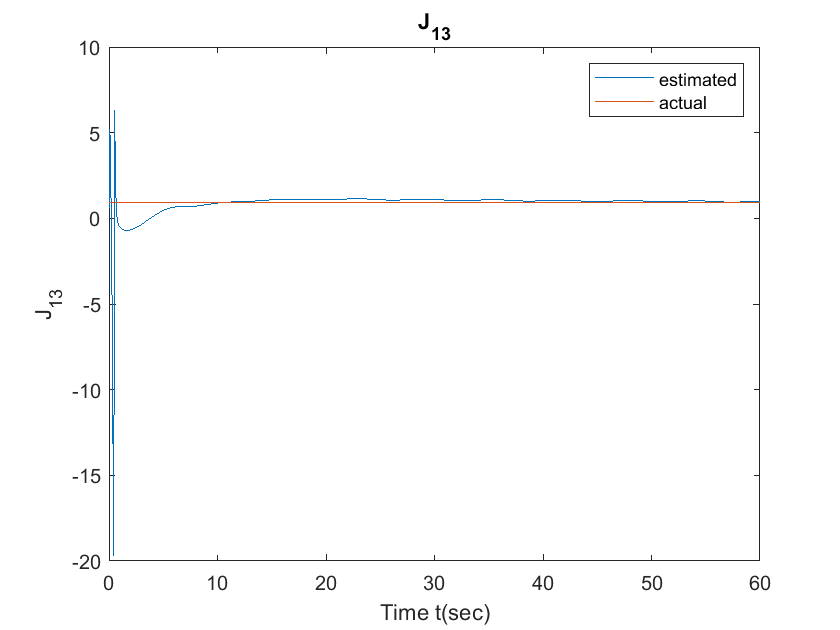

plot(t,y(:,10))
hold on
plot([0 10 20 30 40 50 60],[0.9 0.9 0.9 0.9 0.9 0.9 0.9])
title('J_{13}');
xlabel('Time t(sec)');
ylabel('J_{13}');
legend('estimated','actual')

hold off

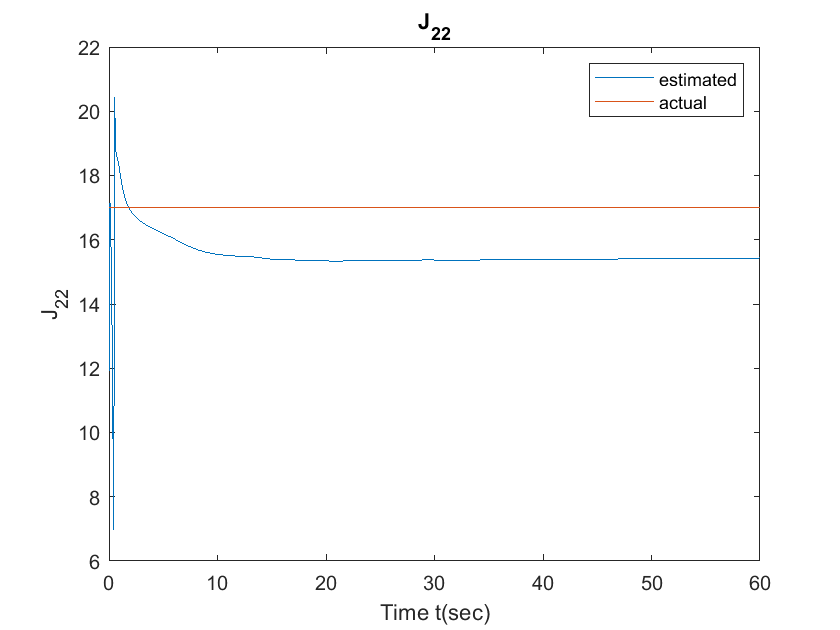

plot(t,y(:,11))
hold on
plot([0 10 20 30 40 50 60],[17 17 17 17 17 17 17])
title('J_{22}');
xlabel('Time t(sec)');
ylabel('J_{22}');
legend('estimated','actual')

hold off

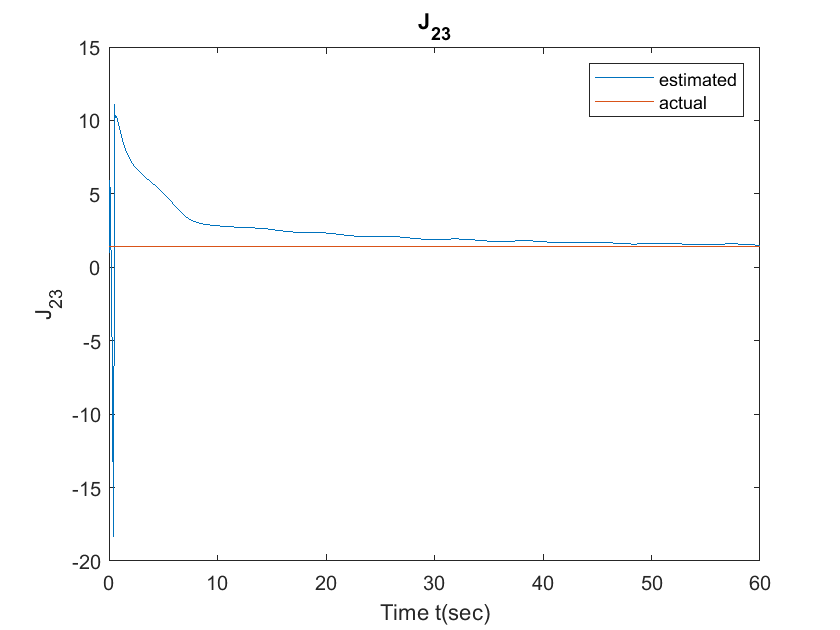

plot(t,y(:,12))
hold on
plot([0 10 20 30 40 50 60],[1.4 1.4 1.4 1.4 1.4 1.4 1.4])
title('J_{23}');
xlabel('Time t(sec)');
ylabel('J_{23}');
legend('estimated','actual')

hold off

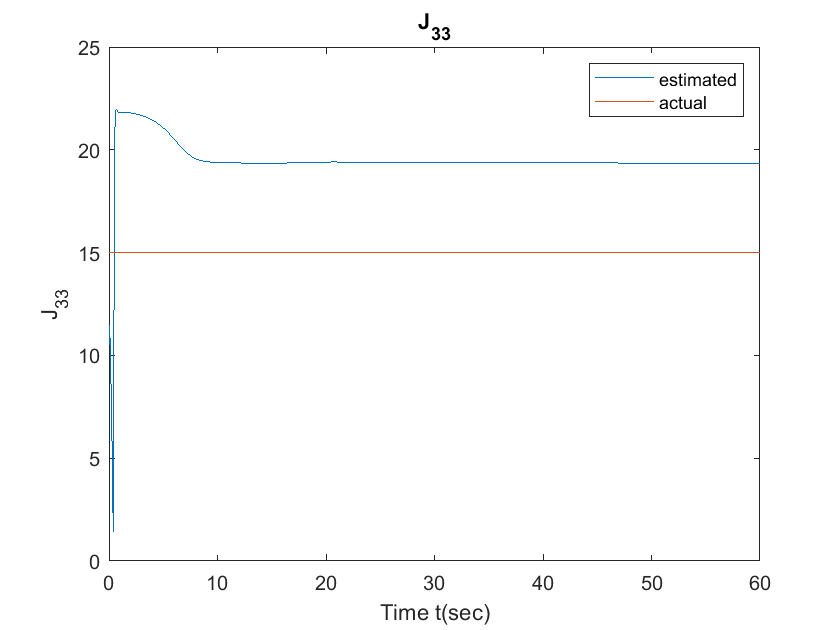

plot(t,y(:,13))
hold on
plot([0 10 20 30 40 50 60],[15 15 15 15 15 15 15])
title('J_{33}');
xlabel('Time t(sec)');
ylabel('J_{33}');
legend('estimated','actual')

%parameter estimated error
hold off

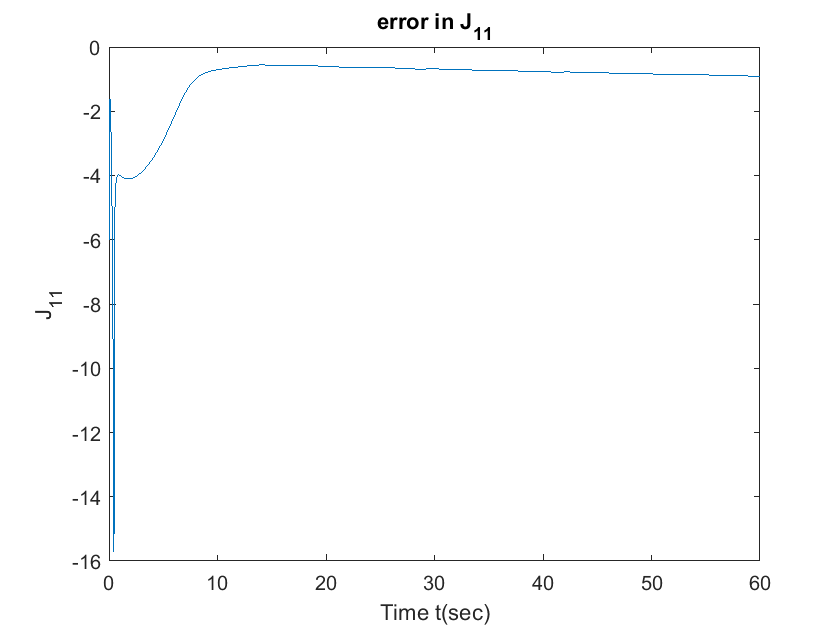

plot(t,e11)
title('error in J_{11}');
xlabel('Time t(sec)');
ylabel('J_{11}');


hold off

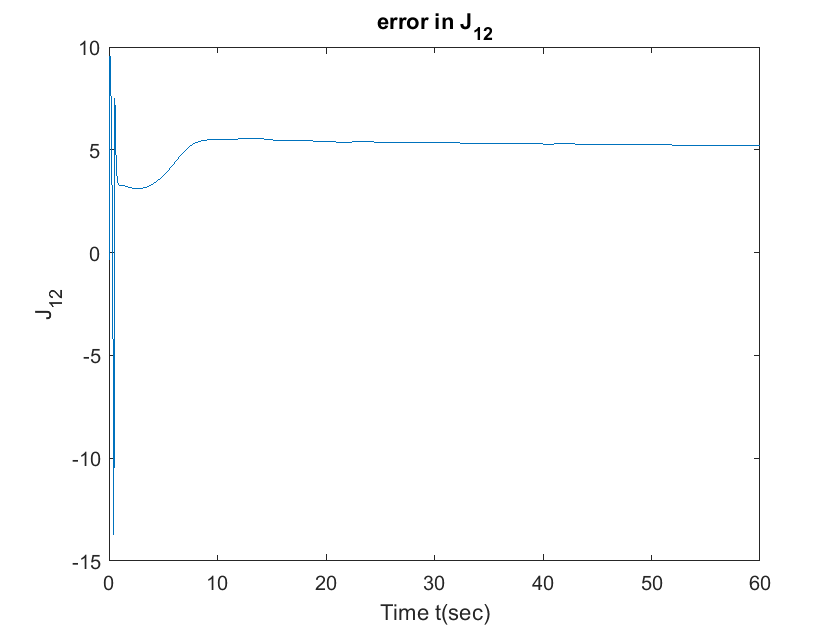

plot(t,e12)
title('error in J_{12}');
xlabel('Time t(sec)');
ylabel('J_{12}');


hold off

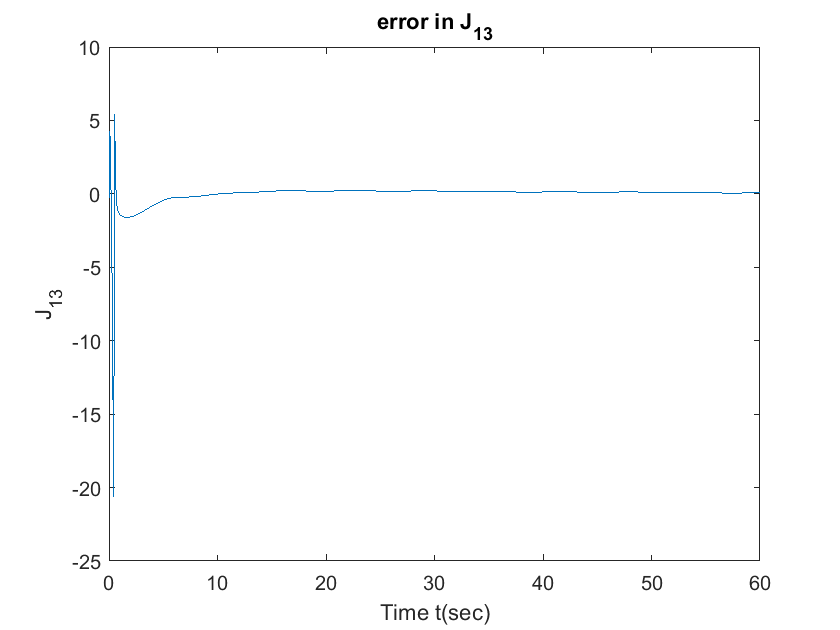

plot(t,e13)
title('error in J_{13}');
xlabel('Time t(sec)');
ylabel('J_{13}');


hold off

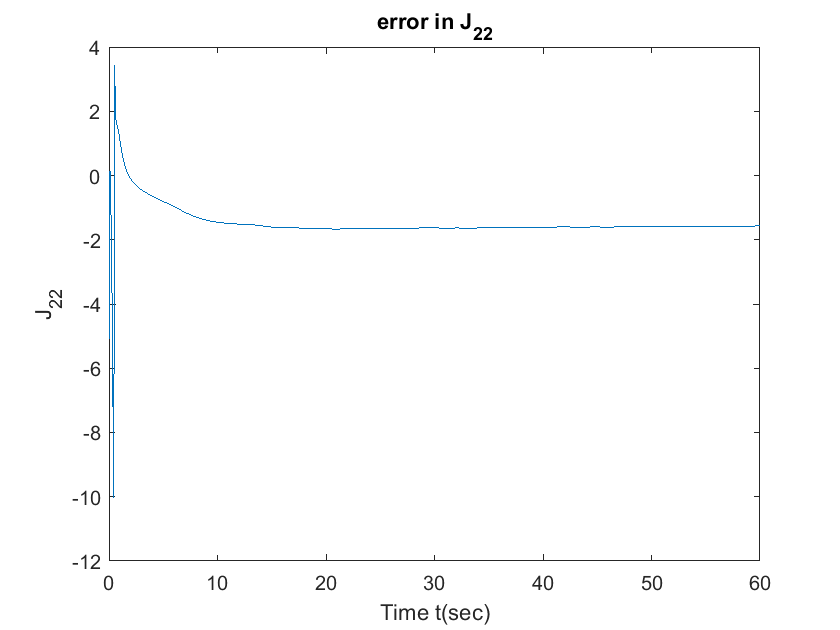

plot(t,e22)
title('error in J_{22}');
xlabel('Time t(sec)');
ylabel('J_{22}');


hold off

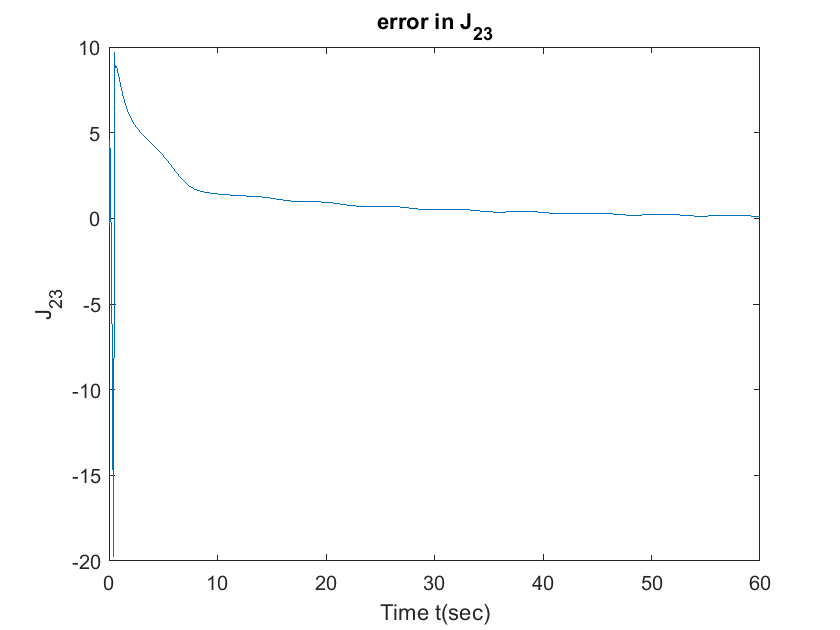

plot(t,e23)
title('error in J_{23}');
xlabel('Time t(sec)');
ylabel('J_{23}');


hold off

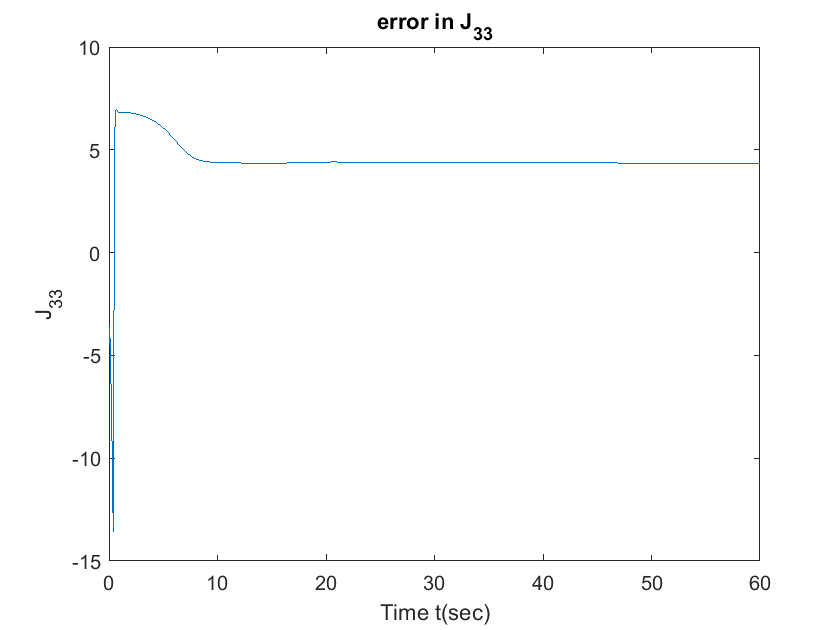

plot(t,e33)
title('error in J_{33}');
xlabel('Time t(sec)');
ylabel('J_{33}');